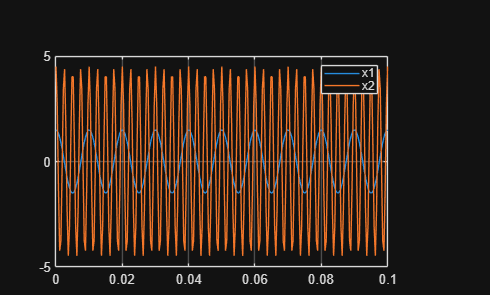

%% Uge 07 – Torsdag, Exercise 1 (A–I)  -- minimal script
clear; close all; clc;

% --------- Parameters from the handout ----------
A1 = 1.5;  A2 = 4.5;
F1 = 100;  F2 = 400;

% Time-grid choice for "analog-style" plots in 1-C
% PDF: N = 2^14 (typeset as 214 in the PDF), Fs = 27 * F1, Tw = N*Ts.  :contentReference[oaicite:3]{index=3}
N  = 2^14;                  % number of samples
Fs = 27 * F1;               % sampling frequency
Ts = 1/Fs;                  % sampling period   (Q: "What is Ts?")  :contentReference[oaicite:4]{index=4}
time_a = (0:N-1)*Ts;        % "analog" time vector from 0 to N*Ts with step Ts

% Qs from 1-C: Why "analog"? Because it's still discrete time samples of a continuous-time expression. 
% Time step is Ts. Length of time_a is N.  :contentReference[oaicite:5]{index=5}

% --------- 1-C: build the five time signals (each in one line) ----------
x1 = A1*cos(2*pi*F1*time_a);
x2 = A2*cos(2*pi*F2*time_a);
x3 = (A1*A2)*cos(2*pi*(F1+F2)*time_a);
x1_plus_x2 = A1*cos(2*pi*F1*time_a) + A2*cos(2*pi*F2*time_a);
x1_times_x2 = (A1*cos(2*pi*F1*time_a)).*(A2*cos(2*pi*F2*time_a));  % note .*  :contentReference[oaicite:6]{index=6}

% Plot a couple in time (you can add others with hold on)
figure('Name','1-C Time signals');
plot(time_a, x1); hold on; plot(time_a, x2);
xlim([0, 10/F1]); grid on; legend('x1','x2');

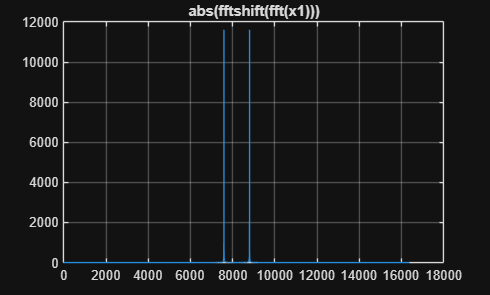


% --------- 1-D: FFT + fftshift (example for x1) ----------
X1 = fft(x1);               % compute DFT
X1 = fftshift(X1);          % reorder to [-Fs/2, Fs/2] order  :contentReference[oaicite:7]{index=7}
figure('Name','1-D raw spectrum of x1');
plot(abs(X1)); grid on; title('abs(fftshift(fft(x1)))');

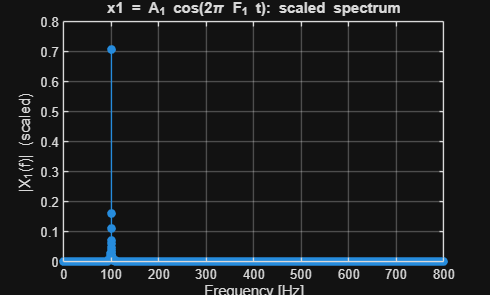


% (Answer the small 1-D questions:)
% - Without abs(): complex values, plot makes little sense for amplitude.  :contentReference[oaicite:8]{index=8}
% - x-axis not yet frequency; it's an index — we fix this in 1-F/1-G.     :contentReference[oaicite:9]{index=9}
% - Amplitudes not yet "as expected" because we must scale by 1/N.        :contentReference[oaicite:10]{index=10}

% --------- 1-E: Amplitude scaling by 1/N ----------
X1s = (fftshift(fft(x1)))/N;   % scaled spectrum  :contentReference[oaicite:11]{index=11}

% --------- 1-F: Frequency bounds and resolution ----------
Fmin = -Fs/2;                 % lower frequency bound
Fmax =  Fs/2;                 % upper frequency bound
dF   = Fs/N;                  % frequency resolution  (ΔF = Fs/N)  :contentReference[oaicite:12]{index=12}
f    = Fmin : dF : Fmax-dF;   % frequency vector (length N), matches fftshift order

% --------- 1-G: Plot adjusted spectrum (scaled + correct freq axis) ----------
figure('Name','1-G Scaled spectrum of x1 vs frequency');
stem(f, abs(X1s), 'filled'); grid on;
xlim([0, 2*F2]);   % zoom so lines are easy to see
xlabel('Frequency [Hz]'); ylabel('|X_1(f)| (scaled)');
title('x1 = A_1 cos(2\pi F_1 t): scaled spectrum');

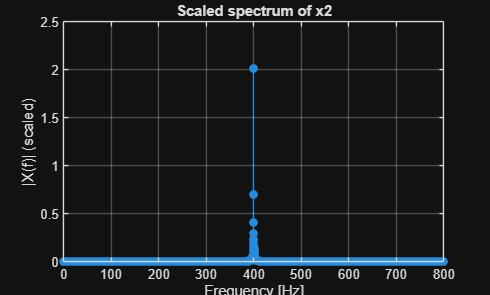

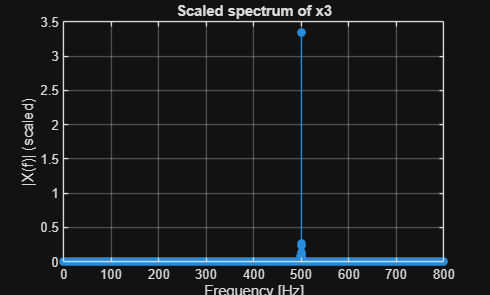

Error: Invalid text character. Check for unsupported symbol, invisible character, or pasting of non-ASCII characters.

% Use data cursor in the figure to read exact line frequencies as asked.  :contentReference[oaicite:13]{index=13}
% Compare to the expected lines from 1-A/1-B.

% --------- 1-H: Do the same for 3 other signals ----------
signals = {'x2','x3','x1\_plus\_x2','x1\_times\_x2'};
for s = 1:numel(signals)
    xt  = eval(signals{s});
    Xs  = fftshift(fft(xt))/N;
    figure('Name',['1-H ',signals{s},' spectrum']);
    stem(f, abs(Xs), 'filled'); grid on;
    xlabel('Frequency [Hz]'); ylabel('|X(f)| (scaled)');
    title(['Scaled spectrum of ',signals{s}]);
    xlim([0, 2*F2]);
end


% --------- 1-I: Inverse FFT (order handling before/after ifft) ----------
% PDF instructs: "just as we shifted before plotting, undo/redo around IFFT"  :contentReference[oaicite:14]{index=14}
X1s_unshift = ifftshift(X1s);           % back to unshifted order for IFFT
x1_recon    = ifft(X1s_unshift * N);    % undo 1/N scaling before IFFT so amplitude matches
% Plot comparison
figure('Name','1-I time-domain: original vs reconstructed x1');
plot(time_a, x1,'-k'); hold on;
scatter(time_a(1:round(end/100):end), real(x1_recon(1:round(end/100):end)),'o');
legend('original x1','reconstructed (sparse markers)');
xlabel('t [s]'); grid on;
